clc; clearvars;

f = 433e6; % frequency in Hertz
Re = 6371e3; % Earth radius in metres
h  = 450e3; % satellite altitude above Earth's surface in metres
elevation_angles = 5:5:90; % elevation angle range in degrees

P_t = -10; % includes HPA, Power of the transmitter in dBw
G_t = 0; % gain of the antenna, in dBi 
L_txsystem = 1; %losses due to feeding lines, connectors, filters, HPA etc in dB
L_fspl = 0; %free space path loss (calculation below) in dB
L_atm = 1; %atmospheric, rain, clouds, fog, ionosphere attenuation + (Diffusion- due to obstacles- neglect) + (Multipath fading- only for terrestrial- neglect) in dB
L_plrz = 3; %polarization mismatch, effectively 0 for circularly polarised antennas in dB
L_point = 1; % pointing losses, add both reciever and transmitter pointing losses in dB

G_r = 8; % gain of ground station in dBi
G_lna_ext = 15; %gain of external lna, see below for effect on F in dBi
L_rxsystem = 1; %losses due to feeding lines, connectors, filters, LNA, demodulators etc in dB

S_datasheet = -136; %sensitivity on datasheet (already includes the internal LNA gain effect an noise spectrum density change) in dBm
T_cold = 200; %At zenith
T_hot  = 1000; %at horizon
T_ant = 0; %Thermal temperature, Tsky(atmospheric thermal temp) + Tgnd(due to sie and back lobes) in K, Calculation below
B_datasheet = 125e3; %Bandwidth of reciever in Hz
SNRrequired_datasheet = -20; %required signal to noise ratio for the reciever to be able to demod the signal in dB

U_bitrate = 293e-6; %bitrate that WE pass, megabits per second
EbNo_threshold = 7.1; %minimum Eb/No required by the reciever, in dB

% Preallocate arrays
LINKMARGINP_via_sensitivity = zeros(size(elevation_angles));
LINKMARGINP_via_ebno = zeros(size(elevation_angles));
r_all = zeros(size(elevation_angles));
L_fspl_all = zeros(size(elevation_angles));
Ts_actual_all = zeros(size(elevation_angles));
CNo_all = zeros(size(elevation_angles));
EbNo_all = zeros(size(elevation_angles));

for i = 1:length(elevation_angles)
    el = elevation_angles(i); % current elevation angle
    fprintf('\n=== Elevation Angle: %.1f° ===\n', el);

    r = sqrt((Re + h)^2 - (Re * cosd(el))^2) - Re * sind(el); % Compute slant range (distance from ground station to satellite)
    EIRP = P_t + G_t - L_txsystem; %effective output power in dBm
    L_fspl = 20*log10(4*pi*r*f/299792458);
    L_prop = L_fspl + L_atm; %propogation losses

    Pr = EIRP - L_prop - L_plrz - L_point + G_r + G_lna_ext - L_rxsystem;
    C = Pr; %recieved power to digital system at reciever end, in dBm
    T_ant = T_cold + (T_hot - T_cold) * (1 - sind(el)); %using Thot an Tcold to model elevation differences
    N = S_datasheet - SNRrequired_datasheet; %noise power
    NF = N + 174 - 10*log10(B_datasheet); %noise figure at datasheet
    F = 10^(NF/10); %noise factor at datasheet

    % if external lna connected - F = Flna + (Frx - 1)/G_lna_ext;

    Tr = (F-1)*290; %Thermal temp at reciever end
    Ts_actual = T_ant + Tr; %Thermal temp of system incluing Tatm and Tr (entire system)
    Ts_spec = F*290; %Thermal temp use by mnufacturer to calculate
    correction = 10*log10(Ts_actual/Ts_spec); %change due to Tatm

    S_actual = S_datasheet + correction; %actual sensitivity of reciever system
    Psensitivity = S_actual;
    LINKMARGINP_via_sensitivity(i) = Pr - Psensitivity;

    No = 1.380649e-23 * Ts_actual; %Noise spectral density in W/Hz
    No = 10*log10(No); %nsd in dBW/Hz

    C_ = C - 30; %C in dBW
    CNo = C_ - No; %received carrier power/noise spectral density in dB-Hz
    EbNo_calculated = CNo - 10*log10(U_bitrate) - 60; %received EbNo in dB, 60 subtracte to convert from Mbps to bps
    LINKMARGINP_via_ebno(i) = EbNo_calculated - EbNo_threshold;

    % Store results for table
    r_all(i) = r;
    L_fspl_all(i) = L_fspl;
    Ts_actual_all(i) = Ts_actual;
    CNo_all(i) = CNo;
    EbNo_all(i) = EbNo_calculated;

    % Print key values for this elevation
    fprintf('Slant range (r): %.2f km\n', r/1e3);
    fprintf('Free-space path loss (L_fspl): %.2f dB\n', L_fspl);
    fprintf('System temperature (Ts_actual): %.2f K\n', Ts_actual);
    fprintf('C/N0: %.2f dB-Hz\n', CNo);
    fprintf('Eb/No: %.2f dB\n', EbNo_calculated);
    fprintf('Link Margin (via Eb/No): %.2f dB\n', LINKMARGINP_via_ebno(i));
    fprintf('------------------------------------------\n');
end


=== Elevation Angle: 5.0° ===


Slant range (r): 1943.68 km


Free-space path loss (L_fspl): 150.95 dB


System temperature (Ts_actual): 2104.10 K


C/N0: 29.42 dB-Hz


Eb/No: 4.75 dB


Link Margin (via Eb/No): -2.35 dB


------------------------------------------



=== Elevation Angle: 10.0° ===


Slant range (r): 1569.57 km


Free-space path loss (L_fspl): 149.09 dB


System temperature (Ts_actual): 2034.90 K


C/N0: 31.42 dB-Hz


Eb/No: 6.75 dB


Link Margin (via Eb/No): -0.35 dB


------------------------------------------



=== Elevation Angle: 15.0° ===


Slant range (r): 1293.07 km


Free-space path loss (L_fspl): 147.41 dB


System temperature (Ts_actual): 1966.77 K


C/N0: 33.25 dB-Hz


Eb/No: 8.58 dB


Link Margin (via Eb/No): 1.48 dB


------------------------------------------



=== Elevation Angle: 20.0° ===


Slant range (r): 1089.70 km


Free-space path loss (L_fspl): 145.92 dB


System temperature (Ts_actual): 1900.20 K


C/N0: 34.89 dB-Hz


Eb/No: 10.22 dB


Link Margin (via Eb/No): 3.12 dB


------------------------------------------



=== Elevation Angle: 25.0° ===


Slant range (r): 938.75 km


Free-space path loss (L_fspl): 144.63 dB


System temperature (Ts_actual): 1835.73 K


C/N0: 36.33 dB-Hz


Eb/No: 11.66 dB


Link Margin (via Eb/No): 4.56 dB


------------------------------------------



=== Elevation Angle: 30.0° ===


Slant range (r): 824.96 km


Free-space path loss (L_fspl): 143.51 dB


System temperature (Ts_actual): 1773.82 K


C/N0: 37.60 dB-Hz


Eb/No: 12.94 dB


Link Margin (via Eb/No): 5.84 dB


------------------------------------------



=== Elevation Angle: 35.0° ===


Slant range (r): 737.78 km


Free-space path loss (L_fspl): 142.54 dB


System temperature (Ts_actual): 1714.96 K


C/N0: 38.72 dB-Hz


Eb/No: 14.05 dB


Link Margin (via Eb/No): 6.95 dB


------------------------------------------



=== Elevation Angle: 40.0° ===


Slant range (r): 669.99 km


Free-space path loss (L_fspl): 141.70 dB


System temperature (Ts_actual): 1659.59 K


C/N0: 39.70 dB-Hz


Eb/No: 15.03 dB


Link Margin (via Eb/No): 7.93 dB


------------------------------------------



=== Elevation Angle: 45.0° ===


Slant range (r): 616.67 km


Free-space path loss (L_fspl): 140.98 dB


System temperature (Ts_actual): 1608.14 K


C/N0: 40.56 dB-Hz


Eb/No: 15.89 dB


Link Margin (via Eb/No): 8.79 dB


------------------------------------------



=== Elevation Angle: 50.0° ===


Slant range (r): 574.38 km


Free-space path loss (L_fspl): 140.36 dB


System temperature (Ts_actual): 1560.99 K


C/N0: 41.30 dB-Hz


Eb/No: 16.63 dB


Link Margin (via Eb/No): 9.53 dB


------------------------------------------



=== Elevation Angle: 55.0° ===


Slant range (r): 540.74 km


Free-space path loss (L_fspl): 139.84 dB


System temperature (Ts_actual): 1518.50 K


C/N0: 41.95 dB-Hz


Eb/No: 17.28 dB


Link Margin (via Eb/No): 10.18 dB


------------------------------------------



=== Elevation Angle: 60.0° ===


Slant range (r): 514.02 km


Free-space path loss (L_fspl): 139.40 dB


System temperature (Ts_actual): 1481.00 K


C/N0: 42.50 dB-Hz


Eb/No: 17.83 dB


Link Margin (via Eb/No): 10.73 dB


------------------------------------------



=== Elevation Angle: 65.0° ===


Slant range (r): 493.01 km


Free-space path loss (L_fspl): 139.03 dB


System temperature (Ts_actual): 1448.77 K


C/N0: 42.95 dB-Hz


Eb/No: 18.29 dB


Link Margin (via Eb/No): 11.19 dB


------------------------------------------



=== Elevation Angle: 70.0° ===


Slant range (r): 476.81 km


Free-space path loss (L_fspl): 138.74 dB


System temperature (Ts_actual): 1422.07 K


C/N0: 43.33 dB-Hz


Eb/No: 18.66 dB


Link Margin (via Eb/No): 11.56 dB


------------------------------------------



=== Elevation Angle: 75.0° ===


Slant range (r): 464.78 km


Free-space path loss (L_fspl): 138.52 dB


System temperature (Ts_actual): 1401.08 K


C/N0: 43.61 dB-Hz


Eb/No: 18.94 dB


Link Margin (via Eb/No): 11.84 dB


------------------------------------------



=== Elevation Angle: 80.0° ===


Slant range (r): 456.47 km


Free-space path loss (L_fspl): 138.37 dB


System temperature (Ts_actual): 1385.97 K


C/N0: 43.82 dB-Hz


Eb/No: 19.15 dB


Link Margin (via Eb/No): 12.05 dB


------------------------------------------



=== Elevation Angle: 85.0° ===


Slant range (r): 451.60 km


Free-space path loss (L_fspl): 138.27 dB


System temperature (Ts_actual): 1376.87 K


C/N0: 43.94 dB-Hz


Eb/No: 19.27 dB


Link Margin (via Eb/No): 12.17 dB


------------------------------------------



=== Elevation Angle: 90.0° ===


Slant range (r): 450.00 km


Free-space path loss (L_fspl): 138.24 dB


System temperature (Ts_actual): 1373.82 K


C/N0: 43.98 dB-Hz


Eb/No: 19.31 dB


Link Margin (via Eb/No): 12.21 dB


------------------------------------------


% Produce table of results
Results = table(elevation_angles.', r_all.'/1e3, L_fspl_all.', Ts_actual_all.', ...
    CNo_all.', EbNo_all.', LINKMARGINP_via_sensitivity.', LINKMARGINP_via_ebno.', ...
    'VariableNames', {'Elevation_deg', 'SlantRange_km', 'L_fspl_dB', 'Ts_K', ...
    'CNo_dBHz', 'EbNo_dB', 'LinkMargin_Sens_dB', 'LinkMargin_EbNo_dB'});

disp(Results);

    Elevation_deg    SlantRange_km    L_fspl_dB     Ts_K     CNo_dBHz    EbNo_dB    LinkMargin_Sens_dB    LinkMargin_EbNo_dB
    _____________    _____________    _________    ______    ________    _______    __________________    __________________

          5             1943.7         150.95      2104.1     29.418     4.7498          -1.5258                -2.3502     
         10             1569.6         149.09      2034.9     31.421     6.7519          0.47631               -0.34808     
         15             1293.1         147.41      1966.8     33.252      8.583           2.3074                  1.483     
         20             1089.7         145.92      1900.2     34.887     10.219           3.9432      

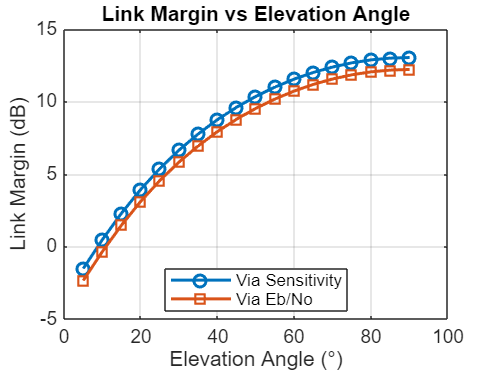

% Plot link margins vs elevation angle
figure;
plot(elevation_angles, LINKMARGINP_via_sensitivity, '-o', 'LineWidth', 1.5); hold on;
plot(elevation_angles, LINKMARGINP_via_ebno, '-s', 'LineWidth', 1.5);
grid on;
xlabel('Elevation Angle (°)');
ylabel('Link Margin (dB)');
title('Link Margin vs Elevation Angle');
legend('Via Sensitivity', 'Via Eb/No', 'Location', 'best');